# L'ambiente MATLAB

Dopo aver aperto MATLAB, dovremmo trovarci nella sitazione raffigurata nell'immagine sottostante. A sinistra vediamo il contenuto della cartella del nostro computer in cui siamo posizionati. La scelta migliore è posizionarsi nella cartella del nostro lavoro. In centro c'è la Command Window, dove è possibile dare i comandi che vogliamo a MATLAB. A destra abbiamo il Workspace, ovvero l'elenco di tutte le variabili che abbiamo generato in questa sessione di MATLAB. 

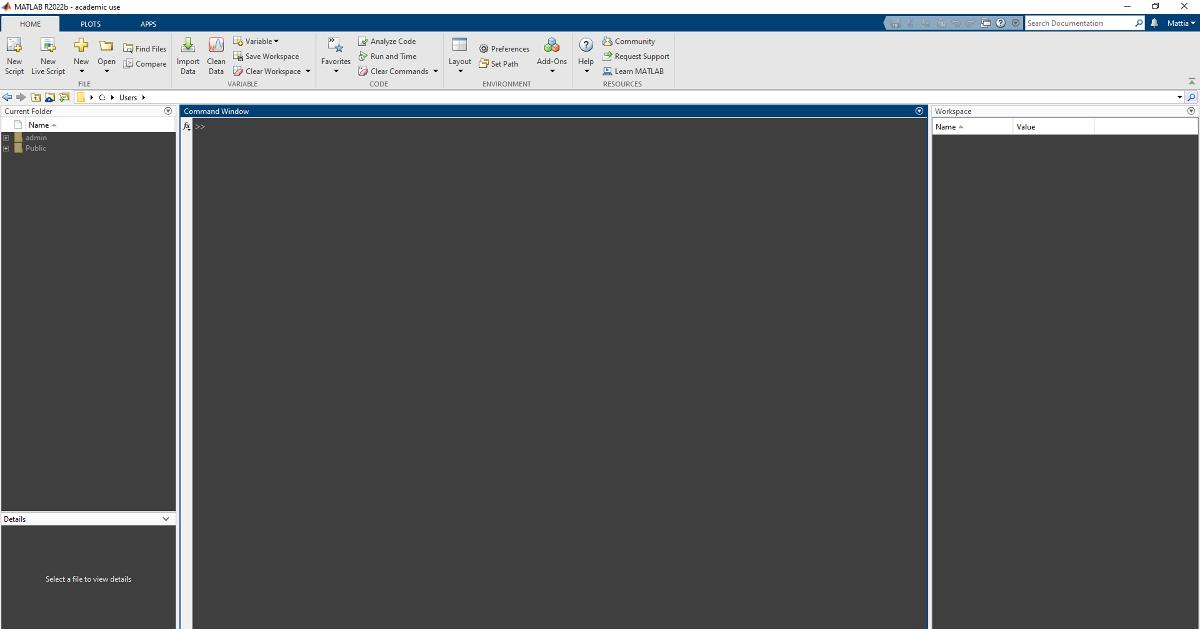

Cliccando su 'New Script' in alto a sinistra nella tab 'HOME' nell'interfaccia di MATLAB apparirà un nuovo riquadro, di fatto un editor di testo. Questo è utile a scrivere tutti i comandi che ci servono, per poterli poi salvare e riutilizzare in futuro, così come modificarli.

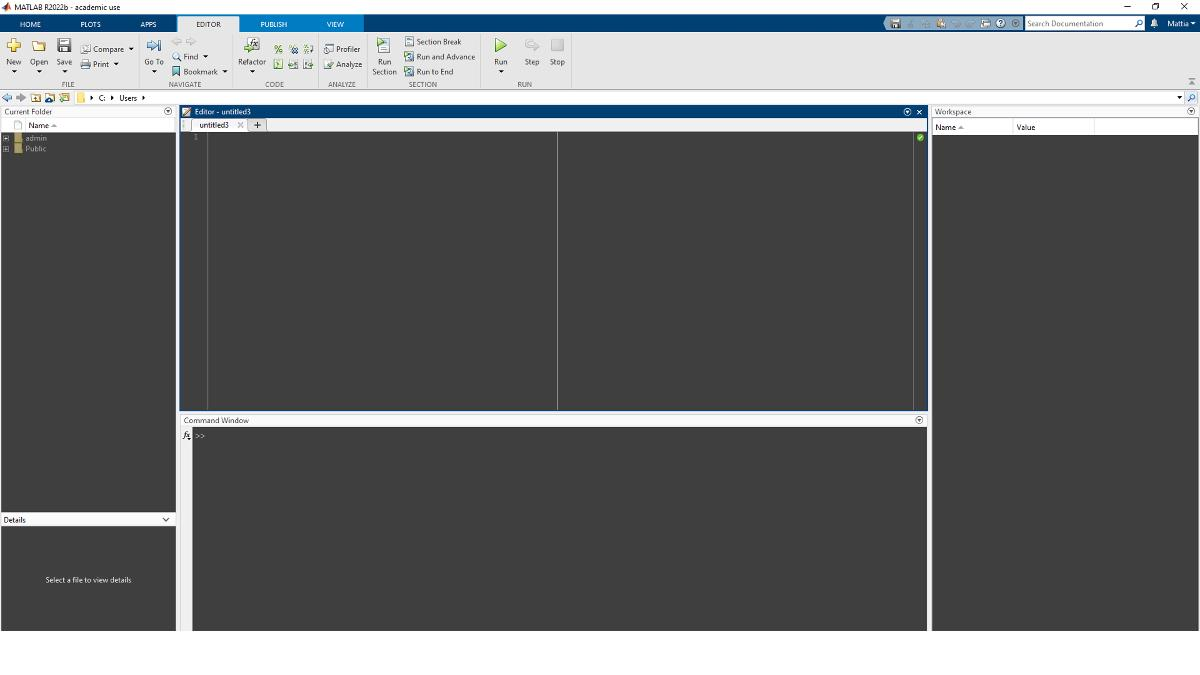

Come qualsiasi linguaggio di programmazione, anche MATLAB "ci chiede di spiegargli" ciò che vogliamo fare secondo le sue regole.

Se scriviamo il codice nella Command Window sarà sufficiente premere il tasto invio per eseguire il comando, se invece stiamo scrivendo il codice nello script, potremo selezionare la riga che vogliamo eseguire e premere F9 (o cliccare sulla riga evidenziata con il tasto destro, e poi cliccare sulla prima voce: "Evaluate selection in Command Window"). Se vogliamo invece eseguire tutto il nostro script premiamo ctrl + invio.

L'esempio più semplice: per attribuire alla variabile chiamata 'a' il valore 1 dovremo digitare quanto segue.

a = 1

a = 1

La riga di codice qui sopra oltre ad attribuire il valore di 1 alla variabile chiamata 'a', rimostrerà nella Command Window (in basso) questa operazione. In molti casi un'operazione eseguita in MATLAB genererà diverse righe di output, e questo potrebbe risultare scomodo. Per ovviare a questo problema, è sufficiente aggiungere ';' dopo la riga di codice. In questo caso, ciò che scriviamo ed eseguiamo nello script non verrà mostrato nella Command Window (ma verrà eseguito da MATLAB).

a = 1;

Nota: tutte le variabili sono listate nella sezione "Workspace" di MATLAB, che nell'esempio nell'immagine qui sopra è a destra. Facendo doppio click (sinistro) su una variabile è possibile vederne il contenuto.

Se per qualche motivo volessimo scrivere una riga di script che non vogliamo che MATLAB "veda", possiamo iniziare la riga con il tasto '%'. In questo modo "commenteremo" la riga (shortcut: ctrl + r / ctrl + t).

% questa è una riga commentata, MATLAB non la prenderà in considerazione, e perciò non la eseguirà.

Una variabile può chiaramente contenere più valori, in questo esempio 5 numeri.

b = [18, 62, 2, 65, 21];

Come nell'esempio, i valori sono contenuti tra parentesi quadre. Utilizzando la virgola come separatore tra i valori, questi vengono concatenati "orizzontalmente". Infatti utilizzando la funzione 'size' per conoscere la dimensione di questa variabile vedremo che la variabile 'b' è composta da una riga e da cinque colonne.

size(b)

ans =      1     5


Utilizzando invece il punto e virgola come separatore tra valori, questi verranno concatenati "verticalmente" (la funzione 'size' ci restituisce infatti i valori 5 e 1, che indicano cinque righe e una colonna):

c = [24; 53; 79; 31; 96];
size(c)

ans =      5     1


Se vogliamo isolare un valore dell'array sulla base della sua posizione (ipotizziamo la seconda posizione) possiamo fare così:

c(2)

ans = 53

Ipotizziamo di voler unire il contenuto di queste variabili in un'unica nuova variabile, che chiameremo d:

% d = [b, c];
% d = [b; c];

Le due righe sono state commentate perchè generano un errore, infatti le dimensioni dei due array di dati non sono compatibili (5 x 1 vs. 1 x 5), potete provare ad eseguire queste righe per vedere l'errore generato.

Possiamo modificare uno dei due array per renderlo compatibile con l'altro utilizzando l'apostrofo:

b

b =     18    62     2    65    21


b'

ans =     18
    62
     2
    65
    21


Perciò:

[c, b']

ans =     24    18
    53    62
    79     2
    31    65
    96    21


oppure, in base all'esigenza specifica:

[c'; b]

ans =     24    53    79    31    96
    18    62     2    65    21


Un array può avere N dimensioni, ipotizziamo di volerne creare uno a due dimensioni, l'utilizzo congiunto di virgola e punto e virgola come separatori ci permette di ottenere il risultato desiderato in una sola riga:

due = [1, 2, 3; 4, 5, 6; 7, 8, 9]

due =      1     2     3
     4     5     6
     7     8     9


Ipotizziamo di avere bisogno di lavorare con parole (stringhe) e non con numeri, in questo caso la formattazione cambierà, useremo infatti le parentesi graffe e apostrofi come in questi esempi:

r = ['d']

r = 'd'

rr = ['d', 't']

rr = 'dt'

rrr = ['45']

rrr = '45'

s = {'abc', 'def', 'ghi' }

s = 1×3 cell array
    {'abc'}    {'def'}    {'ghi'}


Se non abbiamo più bisogno di una variabile:

clear r

Se non abbiamo più bisogno di più di una variabile:

clear rr rrr

Se vogliamo eliminarle tutte:

clear all

Se invece vogliamo ripulire la Command Window (senza però eliminare le variabili dal Workspace sarà sufficiente digitare:

clc

Creare un'unica stringa utilizzando una stringa e una variabile numerica (ipotizziamo di voler caricare un file del partecipante numero 3):

(la funzione num2str() converte un numero in una stringa)

stringa = 'Partecipante_n_';
n = 3;
nomefile = [stringa, num2str(n)]

nomefile = 'Partecipante_n_3'

Una buona strategia per inserire variabili di tipo diverso in un'unica variabile MATLAB è utilizzare le strutture (struct). Eccone un esempio:

dati.giorni = {'Lunedì','Martedì','Mercoledì','Giovedì','Venerdì'};
dati.temperature = [26.3, 27.6, 25.9, 23.1, 22.9];

Cliccando a destra nel Workspace sulla variabile 'dati' vedremo al suo interno che è composta da due array distinti. 

In alcuni casi può succedere che non ci si ricordi come "funzioni" una funzione di MATLAB, e ci risulti necessario capire quali sono gli argomenti che la funzione vuole: tutte le funzioni di MATLAB includono una sezione "guida", che possiamo visualizzare con il comando 'doc'. Ipotizziamo di voler capire quali sono gli argomenti per la funzione 

# Qualche esercizio: